format shortg
clear all

# Oppgave 2

a)

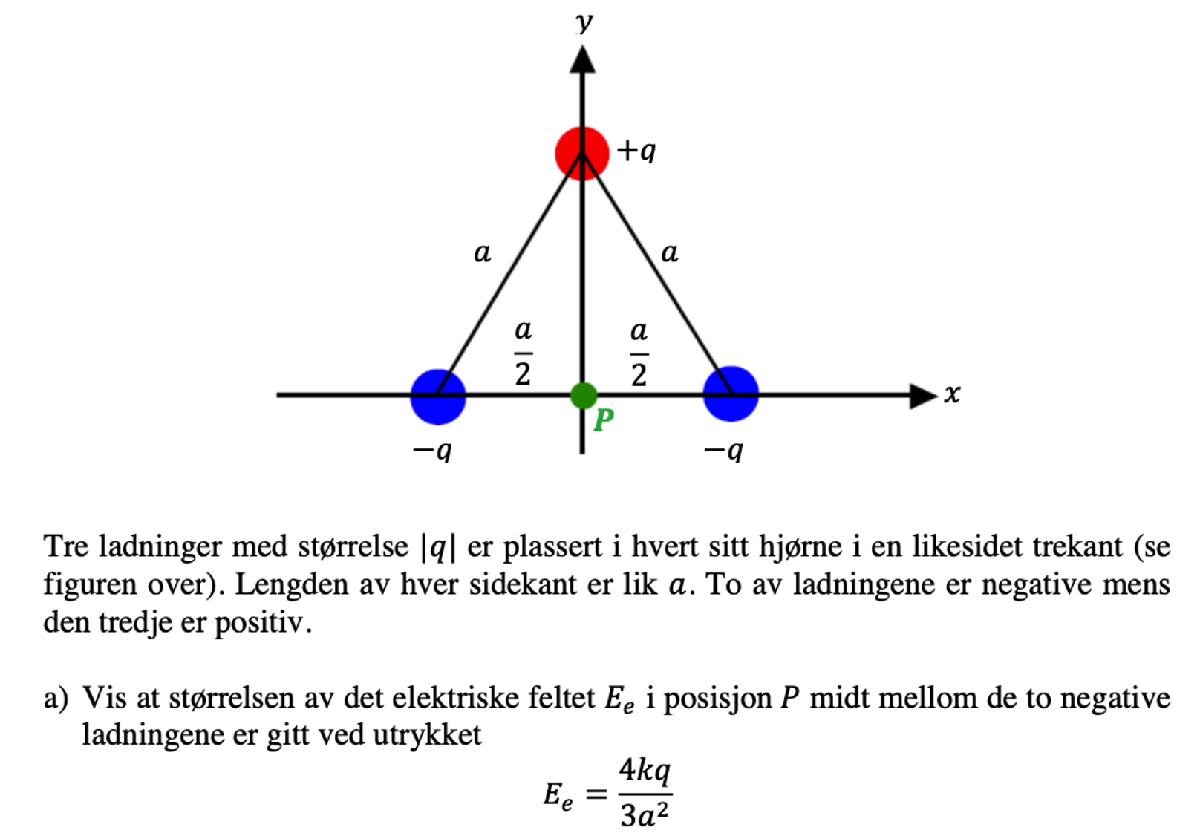

de to blå ladningene vil nulle vherandre ut i posisjon P, altså er det kun feltet fra ladningen +q som oppretter feltet i punktet P


$$r^2 =a^2 -{\left(\frac{a}{2}\right)}^2 =a^2 -\frac{a^2 }{4}=\frac{3a^2 }{4}$$



$$E=k*\frac{q}{r^2 }=k*\frac{q}{3a^2 /4}=k*q*\frac{4}{3a^2 }=\frac{4\mathrm{kq}}{3a^2 }$$


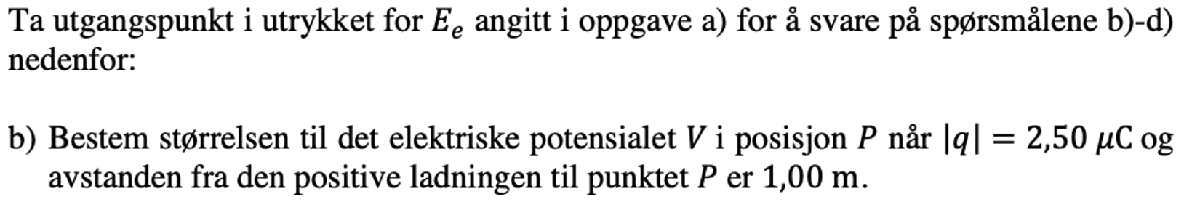

q = 2.50 * 10^-6;
signif(PotensialFraPunktladning(0, q, 1), 3)

ans =        22500


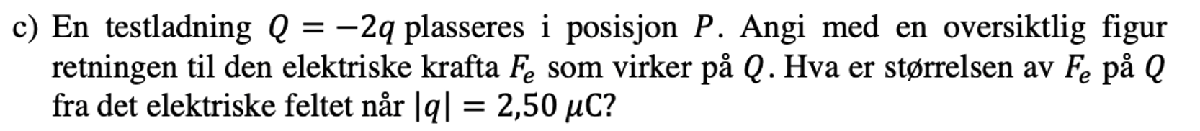

Kraften på den negative ladningen vil være rett oppover.

signif(KraftMellomPunktladninger(0, q, -2*q, 1), 3)

ans =         0.112


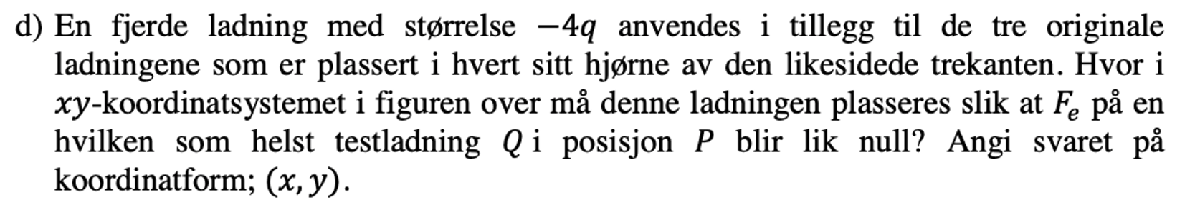

denne ladningen må nøytralisere effekten av den positive ladningn på y-aksen som er der fra før, siden denne ladningen er negativ og større enn den positive må den plassere over den positive, hadde de vært like store kunne vi bare plassert dem oppå hverandre.


$$F_{-4q} =F_q$$



$$k*\frac{4q}{r^2 }=k*\frac{q}{1^2 }$$



$$\frac{r^2 }{4\mathrm{kq}}=\frac{1}{\mathrm{kq}}$$



$$r^2 =4\frac{\mathrm{kq}}{\mathrm{kq}}=4\Rightarrow r=\sqrt{4}=2$$


altså i punktet: $\left(0,2\right)$

# Oppgave 3

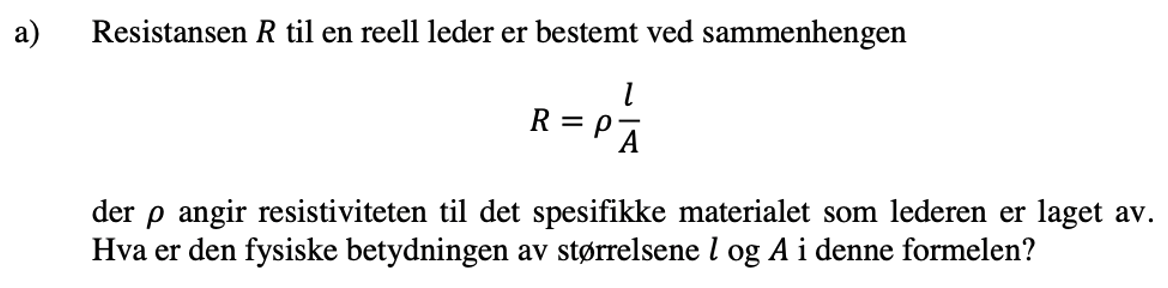

Størrelsene $l$ angir lengden på lederen og $A$ angir Arealet av tverrsnittet til lederen. Disse fysiske størrelsene påvirker Resistansen i at jo lenger lederen er, jo desto høyerer motstand vil det være i lederen. På motsatt vis vil Arealet av tverrsnittet virke motsatt, ettersom at et større tverrsnitt vil gi en mindre resistans ettersom 

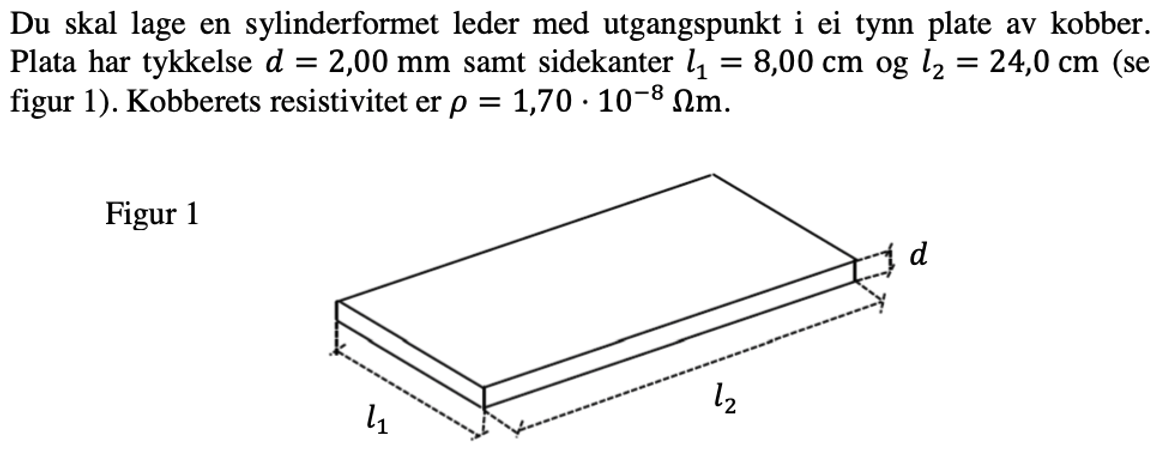

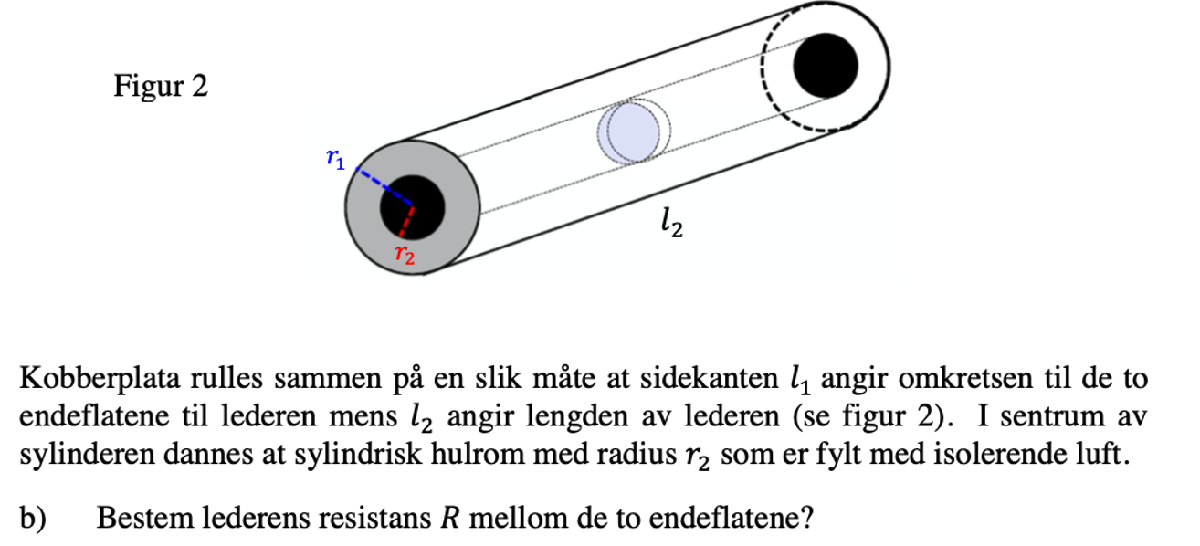

p_kobber = 1.70 * 10^-8; %Ohm meter
d = 2.00 * 10^-3; % meter
l1 = 8.00 * 10^-2; % meter
l2 = 24.0 * 10^-2; % meter

Ønkser først å finne$r_1$, siden vi vet at omkretsen $=l_1$finer vi radiusen med: $O=2\pi r\Rightarrow r=\frac{O}{2\pi }$

og da vet vi at $r_2$ vil være $r_1 -d$

r1 = l1/(2*pi)

r1 =      0.012732


r2 = r1 - d

r2 =      0.010732


da får vi at Arealet av tverrflaten til sylinderen er: $A=\pi r_1^2 -\pi r_2^2$

A = (pi*r1^2)-(pi*r2^2)

A =    0.00014743


siden vi vet at lengden $l=l_2$ får vi Resistansen R mellom endeflatene på:

R = signif(p_kobber*(l2/A), 3)

R =      2.77e-05


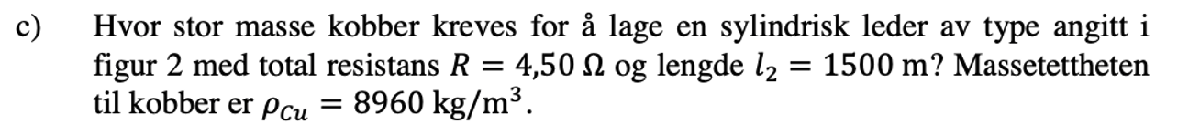

R = 4.5; % Ohm
l2 = 1500; % meter
massetetthet = 8960; % kg/m^3

Først må vi finne Arealet av tverrsnittet for en slik leder: $R=\frac{p*l}{A}\Rightarrow A=\frac{l*p}{R}$

A = (l2 * p_kobber)/R

A =    5.6667e-06


Vi ønsker altså å finne massen til lederen formet som figur 2, som er 1500 meter lang, da finner vi først volumet for denne sylinderen:

V = l2 * A

V =        0.0085


Dette gir en masse på:

Masse = signif(massetetthet * V, 3)

Masse =          76.2


Finner Resistansen for denne lederen:

R = p_kobber*(l2/A)

R =           4.5


# Oppgave 4

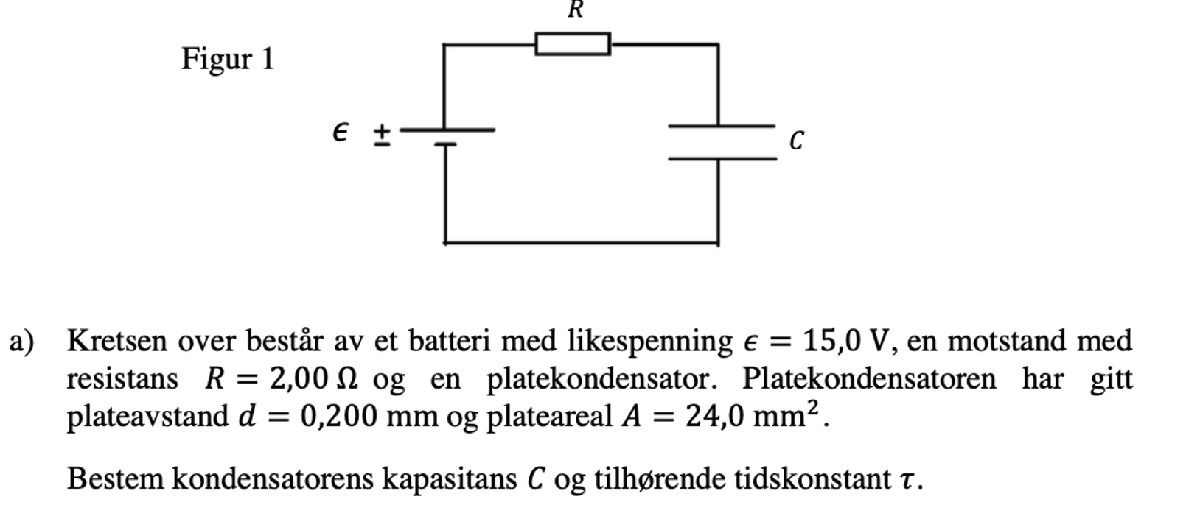

eb = 15;
R = 2;
d = 0.2*10^-3;
A = 24 * 10^-6;


$$C=\epsilon_0 \frac{A}{d}$$


C = e_0*A/d;
signif(C, 3)

ans =      1.06e-12


t = R * C;
signif(t, 3)

ans =      2.13e-12


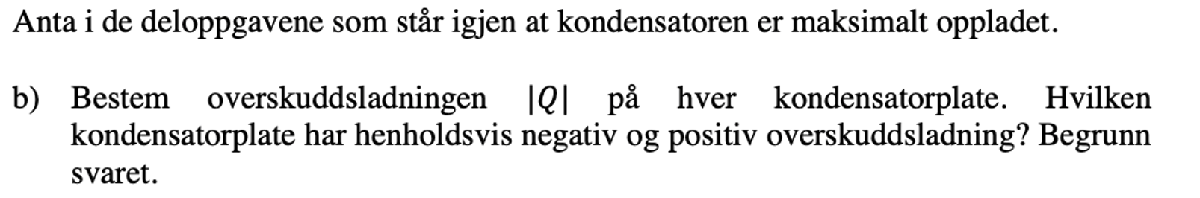

siden kondensatoren er maksimalt oppladet vil det ikke lenger gå strøm, det betyr at potensialforskjellen over kondensatoren er lik den over batteriet, og ladningen for kondensatoren er: $C=\frac{Q}{U}\Rightarrow Q=\mathrm{CU}$

Q = C * eb;
signif(Q, 3)

ans =      1.59e-11


Denne ladningen er lagret på kondesatoren sin nedreplate og er negativt ladet etter ett ovrskudd med elektroner:

Vi vet også at siden kondensatoren motvirker strømmen, og summen av spenningsforskjeller må være null etter kirchoffs 2. lov at den positive platen på kondesnatoren må møte den positive delen av batteriet.


$$E=\frac{U_{\mathrm{ab}} }{d}$$


E = eb/d

E =        75000



$$U=\frac{1}{2}Q*U_{\mathrm{ab}}$$


U = Q * eb/2;
signif(U, 3)

ans =       1.2e-10


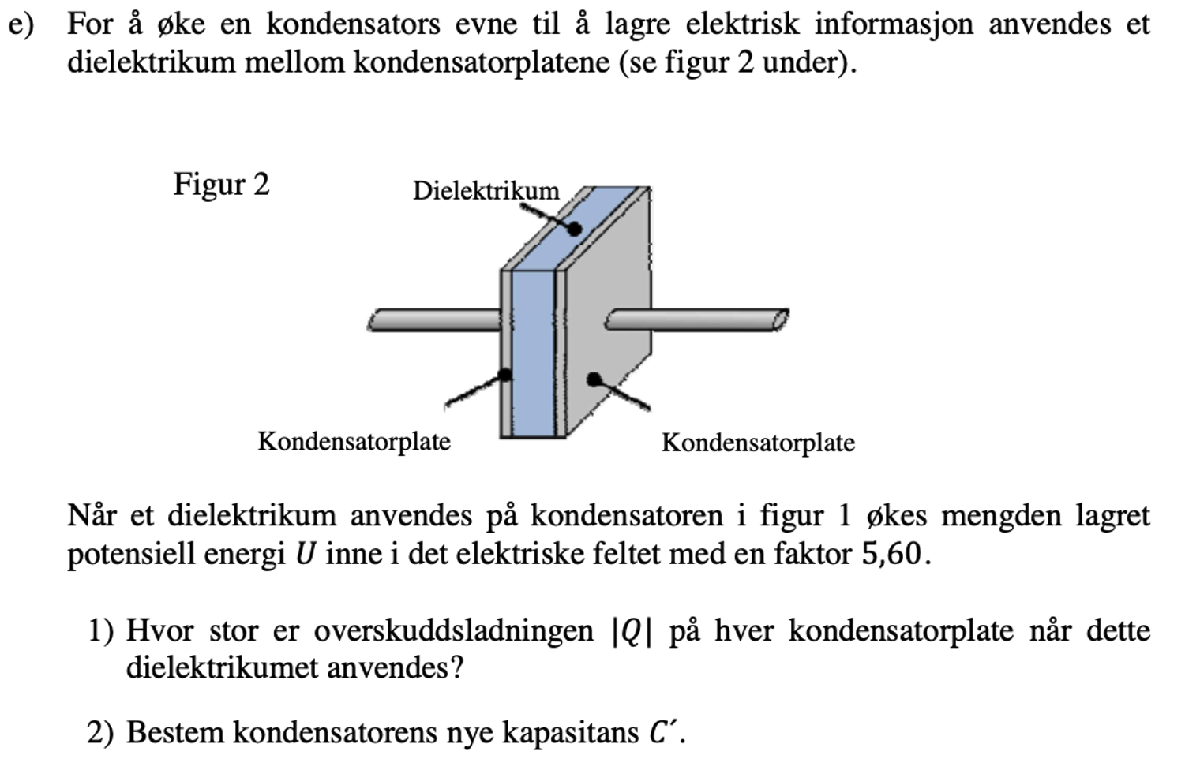

1)

U = U * 5.6;
Q = U / (eb/2);
signif(Q, 3)

ans =      8.93e-11


2)

C = Q/eb

C =      5.95e-12


# Oppgave 5

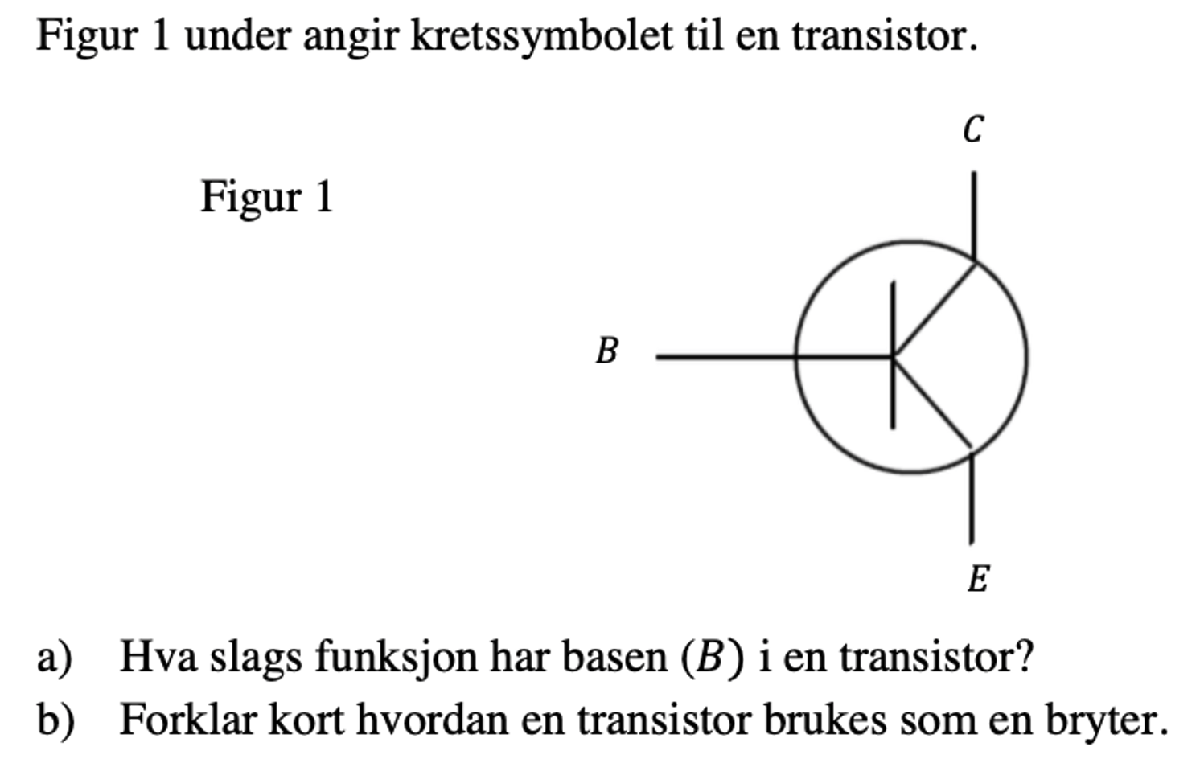

a)

basen sin funkjson er å aktivere transistoren soik at det kan gå strøm fra C og gjennom til E.

b) 

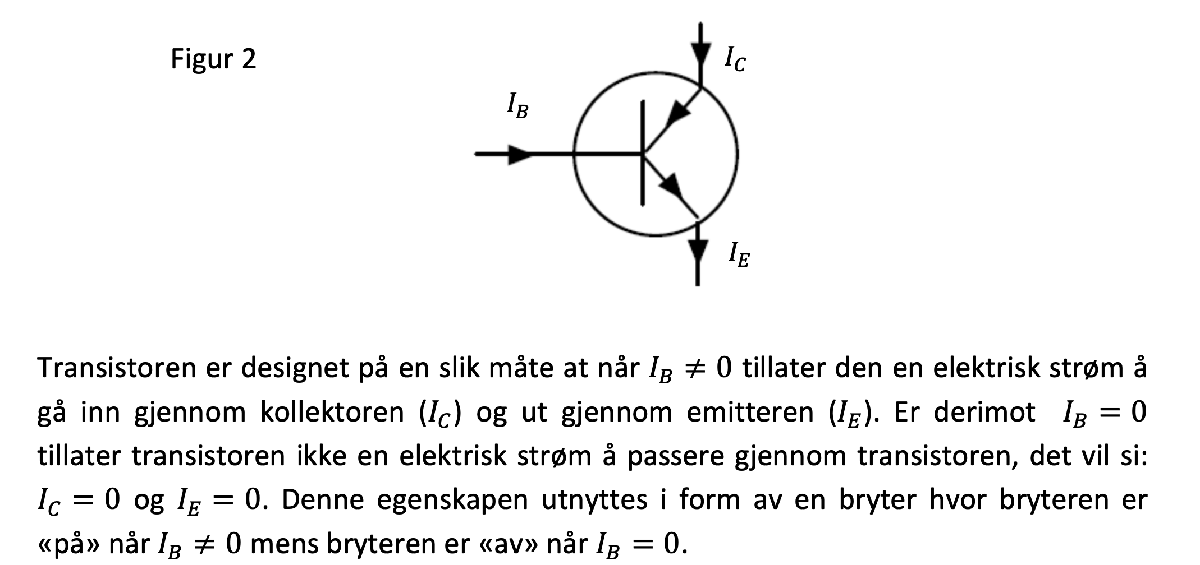¨

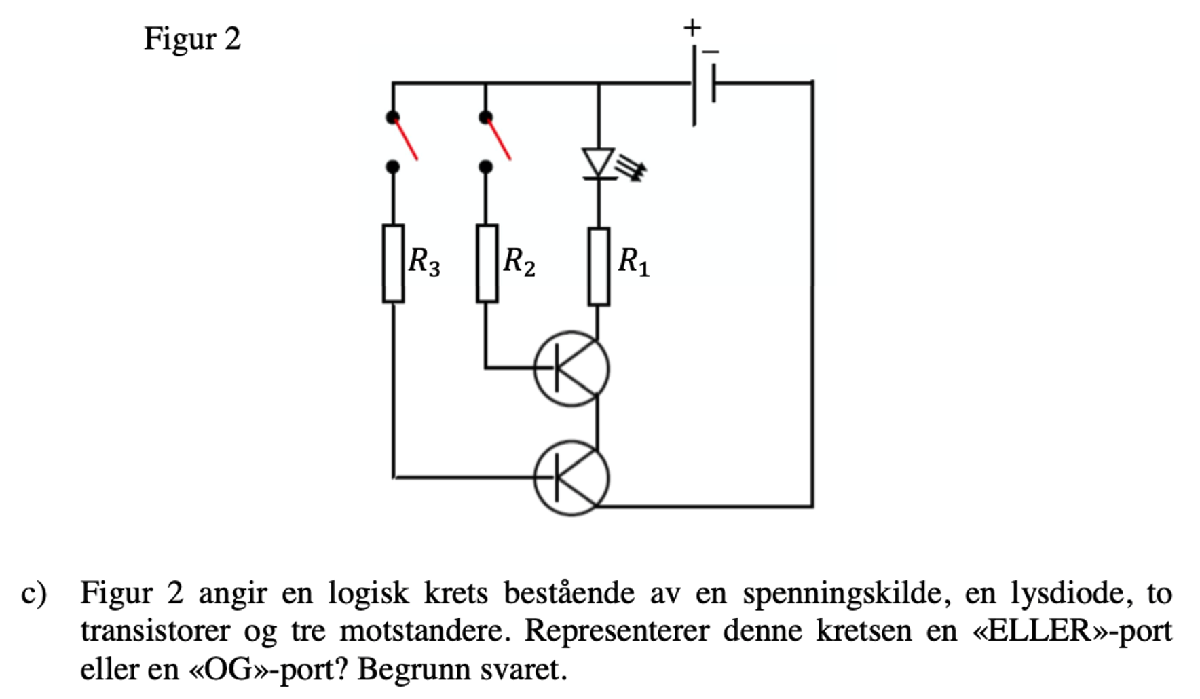

En "Eller" port vil dioden lyse dersom minst en av bryterene er lukket, en "OG" port så må begge bryterene være lukket for at dioden skal lyse:

Av kretsen ser vi at dette er en "OG" krets ettersom at det må komme strøm i begge basene for at strømmen skal kunne gå fra det jeg antar er en npn transistor sin kollektor og ut av emitteren.